## Finding the Port of the Instrument

- Power on the instrument

- Connect the instrument to your computer

- Identify the port that the instrument/s are connected to

clear
% After powering on and connecting the instrument
% Scan ports on computer
port_list = serialportlist;

% Printing out ports
for i = 1:numel(port_list)
    fprintf ("Port #%d: %s\n", i, port_list(i))
end

Port #1: /dev/cu.Bluetooth-Incoming-Port
Port #2: /dev/tty.Bluetooth-Incoming-Port
Port #3: /dev/cu.EthansQC45
Port #4: /dev/tty.EthansQC45
Port #5: /dev/cu.usbserial-AR0KM0M8
Port #6: /dev/tty.usbserial-AR0KM0M8


## Connecting to the Instrument

- Choose the correct port

- Set dev1 variables to the correct port

- Create object and connect to the device

% On Mac you might get something similar to this:
% "/dev/tty.usbserial-AR0KM0M8"

% On Windows you might get somthing similar to this:
% "COM3"
% From device manager you can also find the port number
% Look for "USB Serial Port (COM3)"
% The number will vary between computers

% Set your device variables equal to the ports
dev1 = 6; % Port number of device 1

% Creating an object for the serial communications
device1 = serialport(port_list(dev1), 38400)

device1 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-AR0KM0M8"
             BaudRate: 38400
    NumBytesAvailable: 0

  Show all properties, functions


## Sending the First Commands

- Write a command to the instrument

- Read the information from the instrument

% Get device information from instruments with basic commands
writeline(device1, "*idn?");
dev1idn = readline(device1);
fprintf("Device 1: %s", dev1idn)

Device 1: Arroyo 5305 210819129 v1.51 146


## Changing Temperature and Enabeling Output

- Change the Tset of the device

- Enable the output of the device

- Exploring concatenation

% Changing the Tset
Tset = 26;

% Creating the command and sending it to the device
Tcommand = sprintf("tec:t %d", Tset);
writeline(device1, Tcommand);

% Enable the output
writeline(device1, "tec:out 1");

% A note on concatenation
% Both commands can be combined by using the following syntax
% writeline(device1, "tec:t 25;out 0")

## Logging and Plotting Data

- Log and graph data over a user-defined amount of time

- User-defined log interval (1 Hz by default)

- Log all dynamic values

Here are the user configured variables, adjust them to fit your purposes

% Configure polling frequency in hertz
polling_frequency = 10; %Hz

% Configure acquisition length in seconds
acquisition_length = 5; %sec

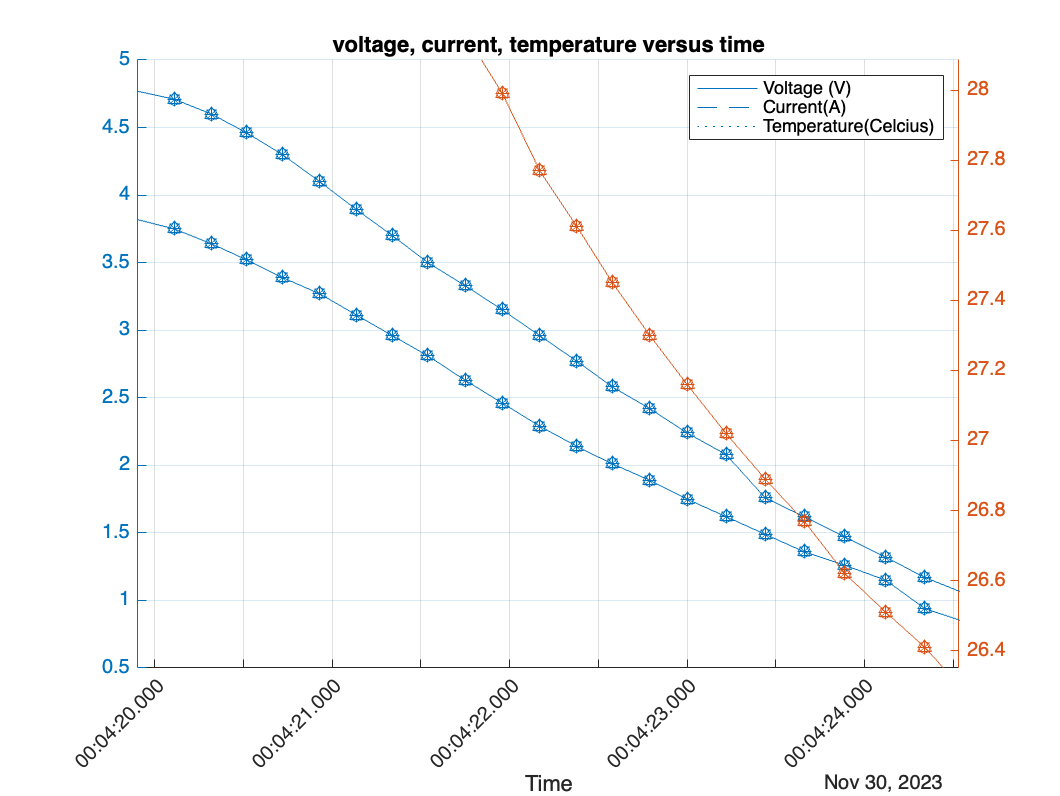

% Data lables for cell array
recorded_values = {"time",  "voltage",  "current",  "temp",  "resistance"};

figure(1)
vct_plot = axes();
hold(vct_plot, "on");



% Begin reading data
for readings = 1:(polling_frequency*acquisition_length)
    % Querey and recieve time, voltage, current, temperature, and resistance
    writeline(device1, "time?;tec:v?;ite?;t?;r?");
    raw_data = readline(device1);

    % Parse raw data
    parsed_data = strings(0);
    [token,~] = split(raw_data, ',');
    parsed_data = [parsed_data ; token];

    % fix time formatting
    time_variables = split(parsed_data(1), ':');
    t = sprintf("%s:%s:%s", time_variables(2:4));
    formatted_time = datetime(t, InputFormat = "HH:mm:ss.SS");
    
    % Create cell array with captured data
    recorded_values(end+1, :) = ...
    {
        formatted_time, 
        str2double(parsed_data(2)),
        str2double(parsed_data(3)),
        str2double(parsed_data(4)),
        str2double(parsed_data(5))
    };

    %Plot voltage, current, temperature versus time
    yyaxis left;
    plot( ...
        [recorded_values{2:end,1}],[recorded_values{2:end,2}], ... % Voltage
        [recorded_values{2:end,1}],[recorded_values{2:end,3}], ... % Current 
        "Parent", vct_plot);
    yyaxis right;
    plot( ...
        [recorded_values{2:end,1}],[recorded_values{2:end,4}], ... % Temperature
        "Parent", vct_plot);
    drawnow;
    pause(1/polling_frequency);

end

% Plot formatting
grid(vct_plot,"on");
title(vct_plot, "voltage, current, temperature versus time");
xlabel(vct_plot, "Time");
xtickangle(vct_plot, 45);
xtickformat(vct_plot,"auto")
legend(vct_plot, "Voltage (V)", "Current(A)", "Temperature(Celcius)");

## Changing of set point and logging of data until stable

- User selected tol time and tol temp

- User-defined log interval (1 Hz by default)

- Change set point and turn output on

- Log all dynamic values

- Log data until stable.

% Configure tol time
tol_time = 5; %sec (0.1 - 50)

% Configure tol temp
tol_temp = 0.1; %C (0.01 - 10)

% Configure polling frequency in hertz
polling_frequency = 10; %Hz

% Changing the Tset
Tset = 35;

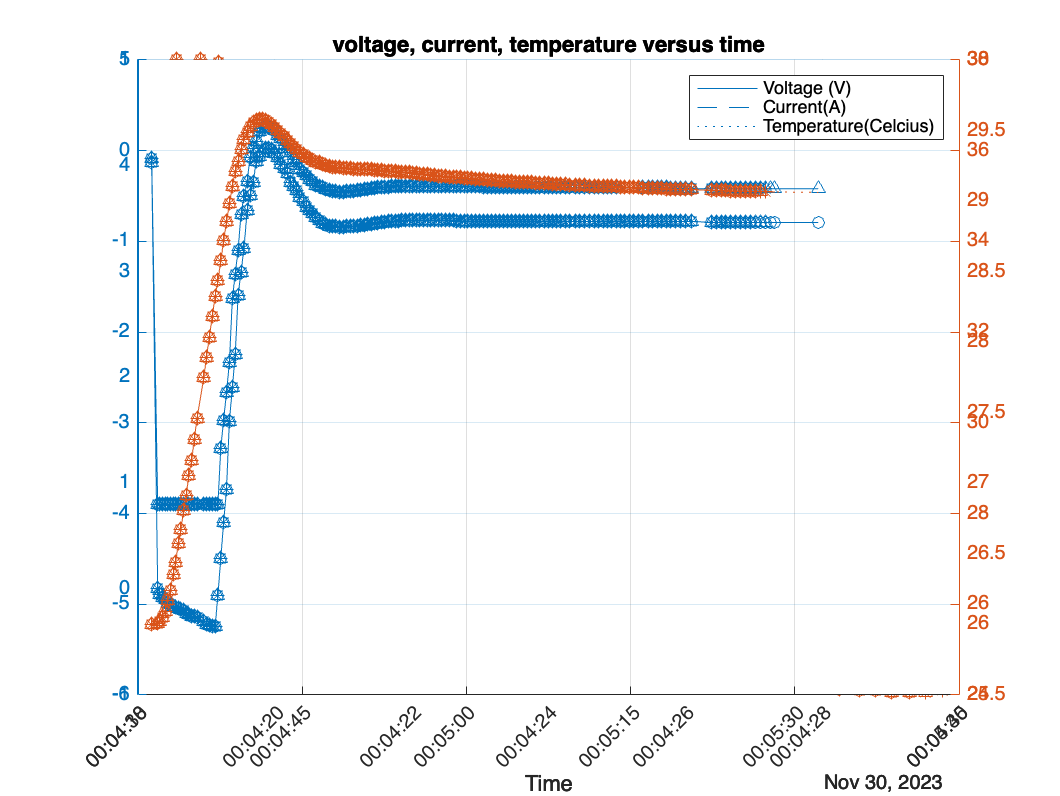

% Data lables for cell array
tol_recorded_values = {"time",  "voltage",  "current",  "temp",  "resistance", "tolerence"};

figure(2)
tol_plot = axes();
hold(tol_plot, "on");

% Creating tolerance command and sending it to the device
tol_command = sprintf("tec:tol %d,%d", tol_temp, tol_time);
writeline(device1, tol_command)

% Creating temp command and sending it to the device
temp_command = sprintf("tec:t %d;out 1", Tset);
writeline(device1, temp_command)

out_tol = 1;

% Begin reading data
while out_tol
    % Querey and recieve time, voltage, current, temperature, and resistance
    writeline(device1, "time?;tec:v?;ite?;t?;r?;cond?");
    raw_data = readline(device1);

    % Parse raw data
    parsed_data = strings(0);
    [token,~] = split(raw_data, ',');
    parsed_data = [parsed_data ; token];
    
    out_tol = bitget(str2double(parsed_data(6)), 10);

    % fix time formatting
    time_variables = split(parsed_data(1), ':');
    t = sprintf("%s:%s:%s", time_variables(2:4));
    formatted_time = datetime(t, InputFormat = "HH:mm:ss.SS");
    
    % Create cell array with captured data
    tol_recorded_values(end+1, :) = ...
    {
        formatted_time, 
        str2double(parsed_data(2)),
        str2double(parsed_data(3)),
        str2double(parsed_data(4)),
        str2double(parsed_data(5)),
        out_tol
    };

    %Plot voltage, current, temperature versus time
    yyaxis left;
    plot( ...
        [tol_recorded_values{2:end,1}],[tol_recorded_values{2:end,2}], ... % Voltage
        [tol_recorded_values{2:end,1}],[tol_recorded_values{2:end,3}], ... % Current 
        "Parent", tol_plot);
    yyaxis right;
    plot( ...
        [tol_recorded_values{2:end,1}],[tol_recorded_values{2:end,4}], ... % Temperature
        "Parent", tol_plot);
    drawnow;
    pause(1/polling_frequency)

end

% Plot formatting
grid(tol_plot,"on");
title(tol_plot, "voltage, current, temperature versus time");
xlabel(tol_plot, "Time");
xtickangle(tol_plot, 45);
xtickformat(tol_plot,"auto")
legend(tol_plot, "Voltage (V)", "Current(A)", "Temperature(Celcius)");

% writeline(device1, "time?;tec:v?;tec:ite?;tec:t?;tec:r?");
% string = readline(device1)
% pstring = "00:01:02:03.22"
% 
% 
% 
% % remain = string
% segments = strings(0)
% [token,remain] = split(string, ',')
% segments = [segments ; token]
% 
% str = "09:12:34.233"
% d = datetime(str, InputFormat="HH:mm:ss.SSS")
% 
% 
% time_variables = split(segments(1), ':')
% 
% t = time_variables(2) + ":" + time_variables(3) + ":" + time_variables(4)
% 
% time_reading = datetime(t, InputFormat = "HH:mm:ss.SS")
% recorded_values = zeros(1,5)
% 
% recorded_values = [recorded_values; t, segments(2:5)']